## Prac 1

close all; clc; clear;

### Exercise 1

General Solution

syms t x(t)
dx = diff(x,t)

$$dx(t) = \frac{\partial }{\partial t}x\left(t\right)$$

EQN = dx + x == 1 % write the differential equation

$$EQN(t) = \frac{\partial }{\partial t}x\left(t\right)+x\left(t\right)=1$$

xsol1 = dsolve(EQN)

$$xsol1 = C_{1}\,{\mathrm{e}}^{-t}+1$$

Particular Solution and Represent it with fplot

% Put the Initial Conditiont0 = ?; 
cond = x(0) == 0;
xsol2 = dsolve(EQN,cond)

$$xsol2 = 1-{\mathrm{e}}^{-t}$$

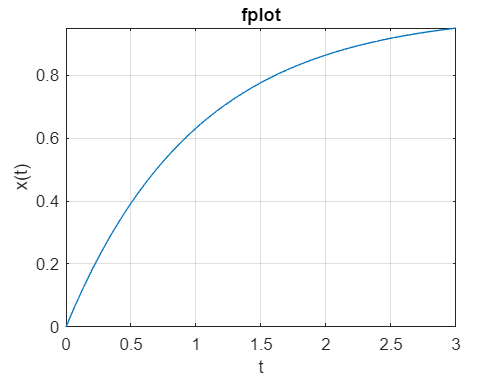

figure; fplot(xsol2,[0,3]);
xlabel('t');ylabel('x(t)');grid on; title('fplot')

Represent the symbolic solution as numeric function

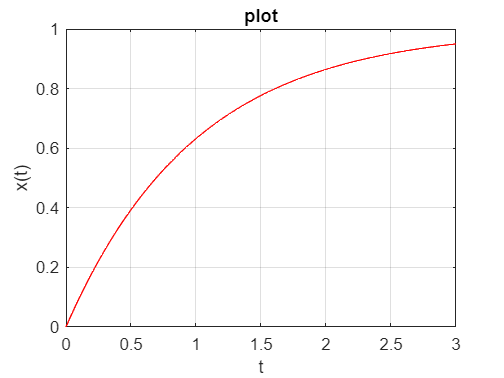

dt = 1e-2; ts = 0:dt:3; % Create a time vector ts between 0 to 3 and dt=0.01
xs = double(subs(xsol2,t,ts)); % Evaluation de solution in ts
figure; plot(ts,xs,'r'); % Plot points (ts,xs) in red color
xlabel('t');ylabel('x(t)');grid on;title('plot')